% cd /home/mic-ciciolla/Documents/università/incompleted/'elective robotics'/'elective 2 - underactuated'/MICHE/hopping-robot-2D/
clear 
pause(0.1)
close all
pause(0.1)

# One-Legged Hopping Robot

#### Parameters [m] and [kg]

g=9.81;

M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; % Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^4; % [Nt/m]

KL2=10^5; % [Nt/m]
BL2=125; % [Nt-s/m]

KG=10^3; % [Nt/m]
BG=75; % [Nt-s/m]

% desired jumping height
H = 0.4;%[m]

#### Initial Conditions

ini_theta1 =0;
ini_theta1_d=0;

ini_theta2 =0;
ini_theta2_d=0;

% ini_w = k0 = 1 ;
ini_w=1;
ini_w_d=0;

% distance [ Leg CoM -- Hip Joint ]
ini_W = ini_w-r1;

## Foot CoM

ini_x0=0;
ini_x0_d=0;

% height
ini_y0 =0; % [m]
ini_y0_d=0;

## Leg CoM

ini_x1=ini_x0+r1*cos(pi/2 - ini_theta1);
ini_x1_d=0;

% height
ini_y1=ini_y0+r1*sin(pi/2 - ini_theta1);
ini_y1_d=0;

## Hip Joint location

ini_xH = ini_x1 + ini_W*cos(pi/2 - ini_theta1);
ini_yH = ini_y1 + ini_W*sin(pi/2 - ini_theta1);

## Body Com

ini_x2=ini_xH + r2*cos(pi/2 - ini_theta2);
ini_x2_d=0;

% height
ini_y2=ini_yH + r2*sin(pi/2 - ini_theta2);
ini_y2_d=0;

## Plotting initial setup

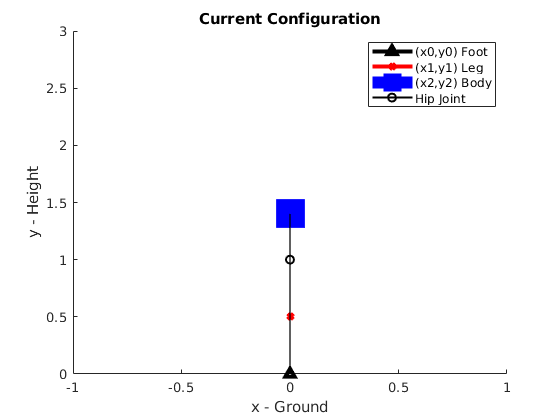

foot(1,1) = ini_x0; foot(1,2) = ini_y0;
leg(1,1) = ini_x1; leg(1,2) = ini_y1;
body(1,1) = ini_x2; body(1,2) = ini_y2;
hip(1,1) = ini_xH; hip(1,2) = ini_yH;

drawRobot(foot,leg,body,hip)

#### Theta1_desired for torque control (equation 1)

theta1_des=0;

**Desired system energy to jump to height H (equation 14) - costant**

desired_energy = M1*g*(H+r1) + M2*g*(H+k0+r2);

**Maximum compression of leg during stance**

deltaw = (M2*g)/KL + sqrt( ((M2^2*g^2)/KL^2) + 2*g*H*(M1+M2)^2/(M2*KL) );

**SIMULINK**

simtime = 10; %simulation time
SimDec=sim('simulink/HoppingRobotModel3',simtime); % Execution of the simulation in Simulink
